sc = 0.0700

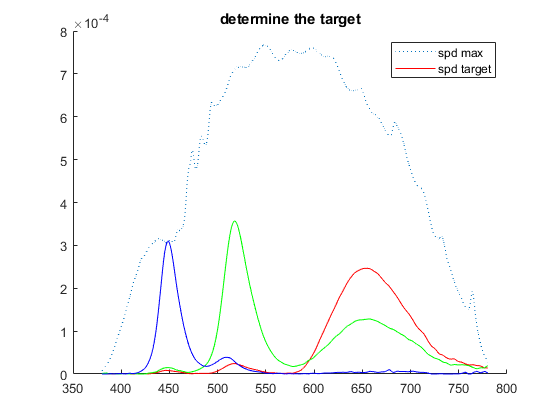

spec_z24x = xlsread('hpz24x_rgb.csv');

spec = spec_z24x(21:end,1:3);
determine_spd_targetx3(spec,ls.spd_max)

function determine_spd_targetx3 (spd_target_orig,spd_max) 
sc = 0.07
spd_target = spd_target_orig .* sc;
clf
hold on
plot(380:780,spd_max,':')
plot(380:780,spd_target(:,1),'r')
plot(380:780,spd_target(:,2),'g')
plot(380:780,spd_target(:,3),'b')
legend('spd max','spd target')
title('determine the target')
end


function determine_spd_target (spd_target_orig,spd_max) 
sc = 0.08
spd_target = spd_target_orig .* sc;
clf
hold on
plot(380:780,spd_max)
plot(380:780,spd_target)
legend('spd max','spd target')
title('determine the target')
end